### Interactions of two RLC branches 

clf; clear; clc
s = tf('s');
R = 1.395e-4*[1,1.0]*2;
L = 1.85e-3*[1.2, 1.0];
C =9.5*[1,1];
Xg = 0.0087;

#### Build a state-space matrix A

A =[(-Xg-R(1))/L(1), -Xg/L(1), -1/L(1), 0;
    -Xg/L(2), (-Xg-R(2))/L(2), 0, -1/L(2);
    1/C(1), 0, 0, 0; 
    0, 1/C(2), 0, 0];
[V,eig_A] = eig(A)

V =    0.7077 + 0.0000i   0.7077 + 0.0000i   0.6684 + 0.0821i   0.6684 - 0.0821i
  -0.6980 - 0.1080i  -0.6980 + 0.1080i   0.7391 + 0.0000i   0.7391 + 0.0000i
  -0.0001 - 0.0104i  -0.0001 + 0.0104i  -0.0049 - 0.0085i  -0.0049 + 0.0085i
  -0.0014 + 0.0102i  -0.0014 - 0.0102i  -0.0065 - 0.0086i  -0.0065 + 0.0086i


eig_A =   -0.0937 + 7.1908i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0937 - 7.1908i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -4.3554 + 5.7617i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -4.3554 - 5.7617i


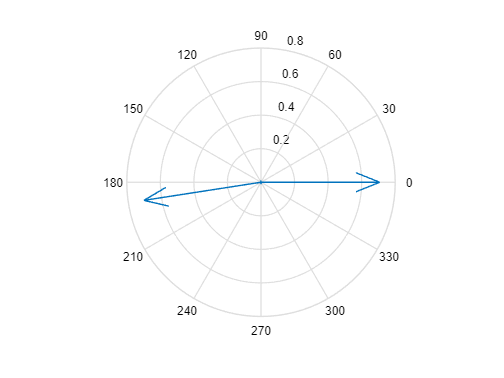

compass(V(:,1)); 

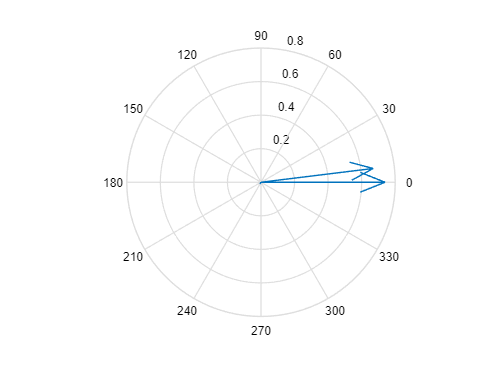

compass(V(:,3))

#### Build the impedance models for frequency domain analysis

Z(1) = R(1)+L(1)*s+1/(C(1)*s);
Z(2) = R(2)+L(2)*s+1/(C(2)*s);
Y(1) = 1/Z(1); Y(2) = 1/Z(2); 
Yt = Y(1)+Y(2)+1/Xg;
G = feedback(Y(1)+Y(2),Xg);

#### Compare the eigenvalues from the state-space model and the closed-loop transfer fucntion

[eig(A), zero(Yt), pole(G)]

ans =   -0.0937 + 7.1908i  -4.3554 + 5.7617i  -4.3554 + 5.7617i
  -0.0937 - 7.1908i  -4.3554 - 5.7617i  -4.3554 - 5.7617i
  -4.3554 + 5.7617i  -0.0937 + 7.1908i  -0.0937 + 7.1908i
  -4.3554 - 5.7617i  -0.0937 - 7.1908i  -0.0937 - 7.1908i


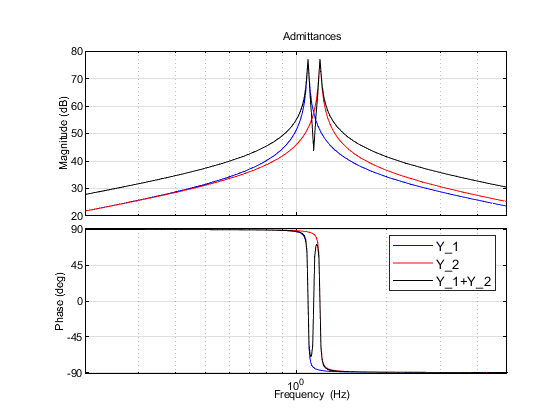

bode_P = bodeoptions;
bode_P.FreqUnits = 'Hz';
bode_P.PhaseWrapping ='on';

figure(1);
bode(Y(1), 'b', Y(2),'r', Y(1)+Y(2), 'k', bode_P); grid on;
%figure(5); hold on;
title('Admittances');
legend('Y_1', 'Y_2', 'Y_1+Y_2','FontSize',10)
xlim([0.2,5])

## Examine each IBR's current response

    Zt = Xg + 1/(Y(1)+Y(2));
    Yt = Y(1) + Y(2) + 1/Xg;

#### Root locus diagram for the loop gain: $(Y_1+Y_2)Z_g$

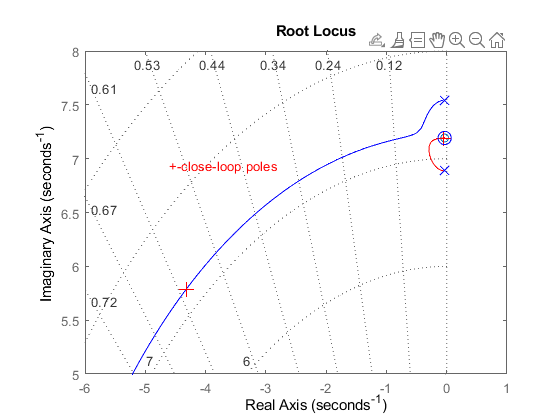

figure(22)
KK=[0.01:0.01:100];
rlocusplot((Y(1)+Y(2))*Xg, KK)
hold on;
pole = rlocus((Y(1)+Y(2))*Xg, 1);
plot(real(pole),imag(pole),'r+','Markersize',10);
hold on;
pole = rlocus((Y(1)+Y(2))*Xg, 0.001);
plot(real(pole),imag(pole),'bx','Markersize',10);
pole = zero((Y(1)+Y(2))*Xg);
plot(real(pole),imag(pole),'bo','Markersize',10);
grid on
xlim([-6,1]);ylim([5,8]);
gtext('+-close-loop poles','color','r');

### compute each current injection to the common bus voltage's transfer function

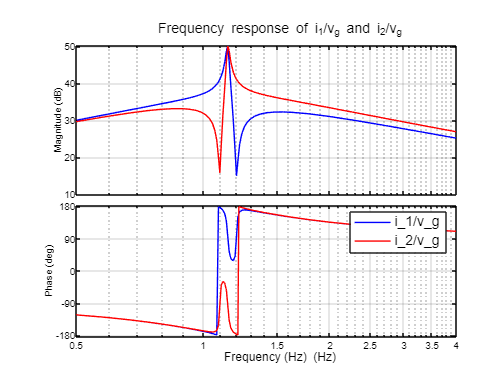

G_v2i = -inv(Y(1)+Y(2))/Zt*[Y(1); Y(2)];
figure;
set(gca,'DefaultTextFontSize',12)
bode(G_v2i(1),'b', G_v2i(2),'r', bode_P); grid on;
hold on;
legend({'i_1/v_g', 'i_2/v_g'},'FontSize',12);
title('Frequency response of i_1/v_g and i_2/v_g', 'FontSize', 12);
%figure_change
xlabel('Frequency (Hz)','FontSize',10);
xlim([0.5,4])

## Examine time-domain responses

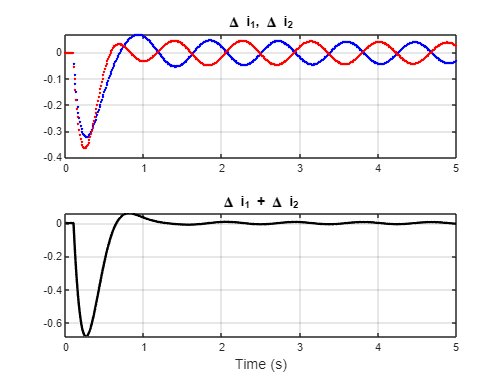

T = [0:0.01:5];
nT = length(T);
U = [zeros(10,1); 0.01*ones(nT-10,1)];
style={'b.','r.', 'b:', 'r:'};
for k=1:2
    temp = lsim(G_v2i(k,1),U, T);
    i_rlc(:,k)= temp;
end

figure;
subplot(2,1,1);hold on;
for k=1:2
    plot(T, i_rlc(:,k),style{k},'LineWidth',2); hold on;
end

title('\Delta i_1, \Delta i_2','FontSize', 12);grid on;box on;
subplot(2,1,2); hold on;
plot(T, i_rlc(:,1)+i_rlc(:,2),'k', 'LineWidth',2);grid on;
title('\Delta i_1 + \Delta i_2','FontSize', 12);
xlabel('Time (s)', 'FontSize', 12)
box on;